# `Project 3`

# `(Sparsh Gupta & Sohum Kothavade)`

# `SEIRD (deterministic) vs SEIRD (stochastic)`

#### `Computational Essay`

`sgupta1@olin.edu                 skothavade@olin.edu`

## `Question `

What are the key differences between the SEIRD model with deterministic parameters observed during COVID-19 and the SEIRD model with stochastic parameters during disease transmission, particularly in how they differ in the peak number of infections throughout the simulation?

## `Methodology/Model`

The stock-and-flow digram for the SEIRD model 

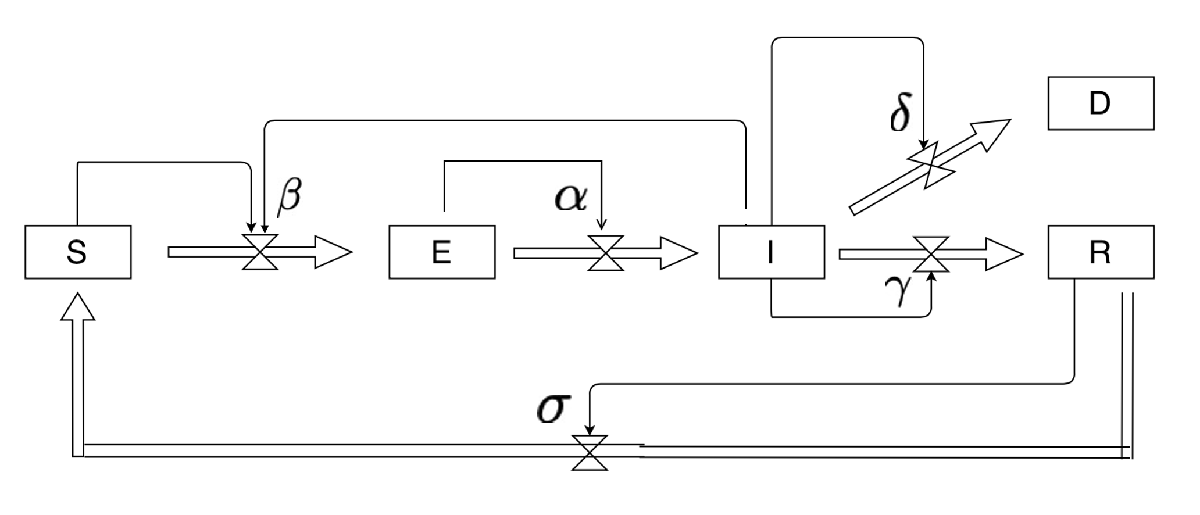

The update equations being used in the SEIRD model


$$S_{n+1} = S_{n} - \beta I S + \sigma R
\\
E_{n+1} = E_{n} - \alpha E  + \beta I S
\\
I_{n+1} = I_{n} - \gamma I  - \delta I  + \alpha E
\\
R_{n+1} = R_{n} - \sigma R  + \gamma I
\\
D_{n+1} = D_{n} + \delta I
$$


The SEIRD model has multiple assumptions, but the greatest being that natural births and deaths cancel out leaving only the deaths by the disease itself. This is an acceptable assumption because natural births and deaths are relatively balanced within the short-term across which the model is simulated. The models also assume that keeping the re-susceptibility parameter the same across both, albeit chosen arbitrarily, does not influence the visible differences in behavior holistically. This assumption is acceptable because the modeling question looks at overall trends in model results and infectivity sensitivity rather than disease-specific characteristics.

Stocks in the SEIRD model:

- S represents the number of Susceptible people in the model

- E represents the number of Exposed people in the model

- I represents the number of Infectious people in the model

- R represents the number of Recovered people in the model

- D represents the number of Dead people in the model

Flows in the SEIRD model:

- The flow from S to E represents susceptible people getting exposed

- The flow from E to I represents exposed people becoming infectious

- The flow from I to D represents infectious people dying

- The flow from I to R represents infectious people recovering

- The flow from R to S represents recovered people becoming re-susceptible

The parameters in the SEIRD (deterministic) model were set by taking into account the following:

$\alpha$** (incubation time): **

The incubation time of COVID is on average 8 days according to the CDC. A person starts at 100% health and is considered infectious at 25% health. With each passing week, a person's current health is multiplied by alpha to calculate their new health. This calibration was used to find a value of 30/100 for alpha where after 8 days a person is considered infectious.

$\beta$** (infectivity): **

The parameter beta is within the range of 0.005 and 0.2. These values were chosen as bounds because below 0.005 the simulation time frame is insufficient to produce results and above 0.2 the metrics measured become almost entirely linear and parallel for both models. The infectivity for the SIR model was standardized to the infectivity of the SEIRD model by aligning their peaks of Wave 1. At the same infectivity, the models behave very differently from the start, which would invalidate Wave 2 results.

$\gamma$** (recovery): **

The recovery time for COVID was found to be approximately one week. A person starts at 100% infectiousness and is considered recovered at 25% infectiousness. With each passing week, a person's current infectiousness is multiplied by gamma to calculate their new infectiousness. This calibration was used to find a value of 1/4 where after 7 days a person is considered healthy and non-infectious.

$\delta$** (death): **

The death rate of COVID is 1/30.

$\sigma$** (re-susceptibility):**

 This parameter is arbitrary such that the models produce results within the simulation window.

The stochatic parameters in the SEIRD (stochastic) model were set by taking into account the following:

$\beta_n$** (infectivity): **

$\gamma_n$** (recovery): **

**Verification:**

There are four verification facts used to ensure that the SEIRD model functions as expected:

- Conservation of People Violated: The total number of people has either exceeded or fallen below the starting value.

- Negative People: A stock is experiencing negative people.

- Extra People found: A stock has more than the initial number of people in the simulation.

- Dead People decreasing: The Dead stock is decreasing.

% assert(all(abs(S + E + I + R + D - 100) < 1e-3), "Conservation of People Violated!")
%
% assert(all(S>=0)||all(E>=0)||all(I>=0)||all(R>=0)||all(D>=0), "Negative People!")
%
% assert(all(S<=100)||all(E<=100)||all(I<=100)||all(R<=100)|| all(D<=100), "Extra People found!")
%
% assert(all((D(2:end)-D(1:(end-1)))>=0), "Dead People decreasing!")


The verification facts used to ensure that the stochastic probability distribution and the parameter values function as expected are:

-  Beta distribution bounds violated: In the SEIRD (stochastic) model, we draw values for the stochatic parameters from Beta Probability Distribution function, and the bounds cannot exceed the interval [0,1]

% for i=1:length(beta_pdf)
%     assert(all(beta_pdf(i) >= 0 & beta_pdf(i) <= 1), "Beta distribution bounds violated!")
%     assert(all(gamma_pdf(i) >= 0 & gamma_pdf(i) <= 1), "Beta distribution bounds violated!")
% end   

#### Sensitivity Analysis using Parameter Sweeps for SEIRD

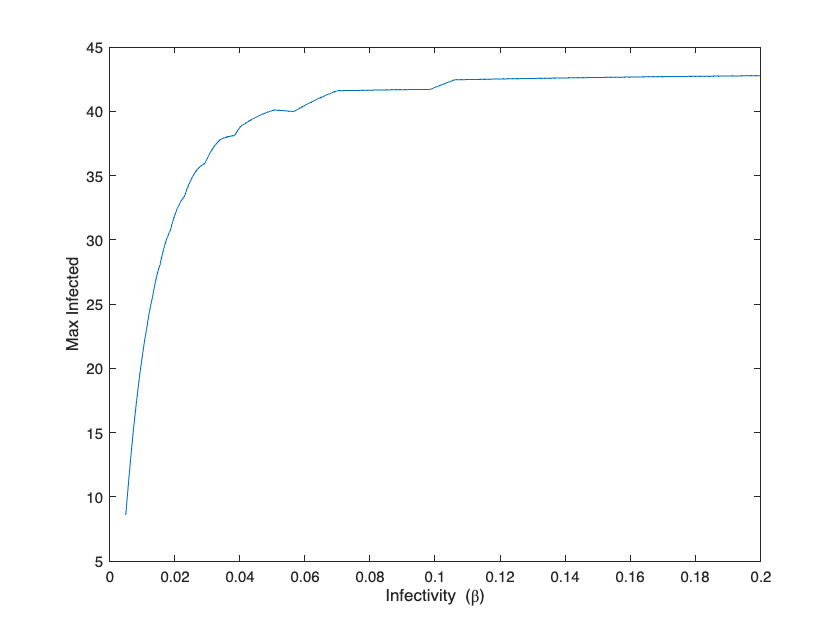

% Time
timestep = 100;

% Parameters
alpha_middle = 0.3;
beta_middle  = 0.037; 
gamma_middle = 0.25;
delta_middle = 0.033;
sigma_middle = 0.015;

% Initial number of people
i_0 = 2;         
s_0 = 100 - i_0;
r_0 = 0;
e_0 = 6;
d_0 = 0;

% Parameter sweep for infectivity (beta)

beta_start = 0.005;
beta_end = 0.2;
Beta_all = linspace(beta_start, beta_end, 500);

% Reserve space for the resulting metric values
Max_all = zeros(size(Beta_all));

% Loop over all beta values
for i = 1 : length(Beta_all)

    % Simulate with the desired beta    
    beta_temp = Beta_all(i);   

    [S, E, I, R, D, W] = simulate_seird(s_0 - e_0, e_0, i_0, r_0, d_0, ...
    alpha_middle, beta_temp, gamma_middle, delta_middle, sigma_middle, timestep);

    % Compute and store the metric value    
    Max_all(i) = max(I);

end

% Visualize the results
figure()
plot(Beta_all, Max_all)
xlabel('Infectivity (\beta)')
ylabel('Max Infected')
% Parameter sweep for recovery (gamma)

gamma_start = 0.01;
gamma_end = 0.6;
Gamma_all = linspace(gamma_start, gamma_end, 500);

% Reserve space for the resulting metric values
Max_all = zeros(size(Gamma_all));

% Loop over all beta values
for i = 1 : length(Gamma_all)

    % Simulate with the desired beta    
    gamma_temp = Gamma_all(i);   

    [S, E, I, R, D, W] = simulate_seird(s_0 - e_0, e_0, i_0, r_0, d_0, ...
    alpha_middle, beta_middle, gamma_temp, delta_middle, sigma_middle, timestep);


    % Compute and store the metric value    
    Max_all(i) = max(I);

end

% Visualize the results
figure()
plot(Gamma_all, Max_all)
xlabel('Recovery (\gamma)')
ylabel('Max Infected')

#### **Model Simulation with 100 people**

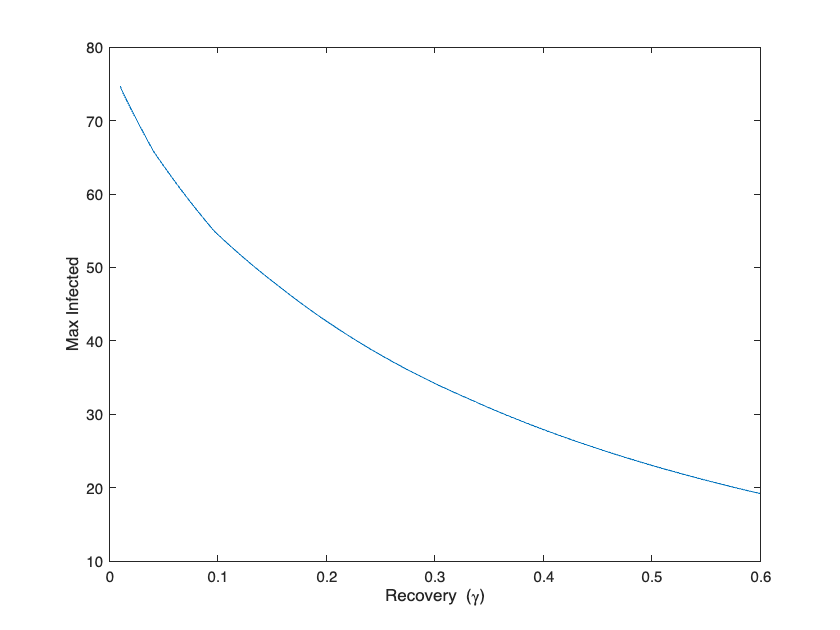

% SEIRD (deterministic) parameters
alpha = 0.3;                             % Infection rate
beta  = 0.037;                           % Exposure rate
gamma = 0.25;                            % Recovery rate
delta = 0.033;                           % Death rate

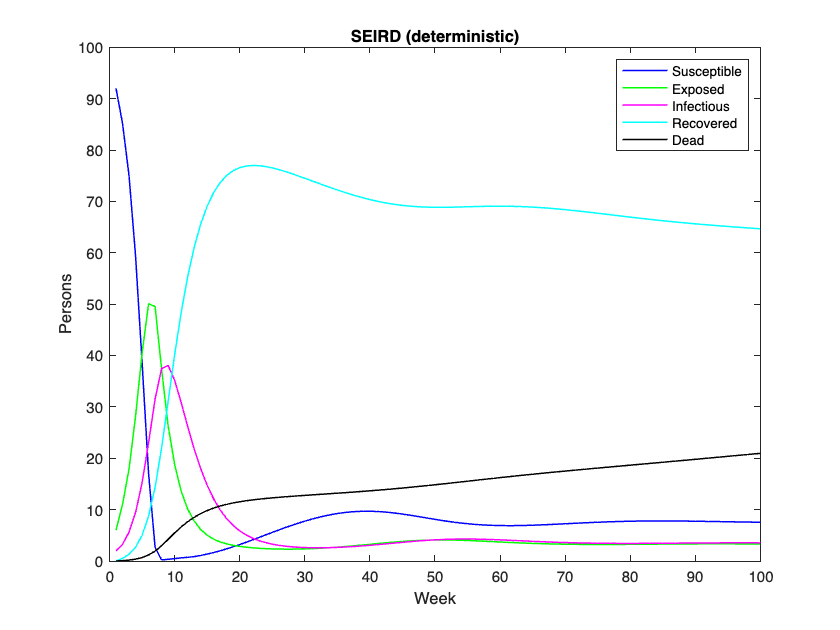

sigma = 0.015;                           % Re-susceptible rate

% Time period
timestep = 100;

% Initial number of people
i_0 = 2;         
s_0 = 100 - i_0;
r_0 = 0;
e_0 = 6;
d_0 = 0;


% SEIRD simulation
[S, E, I, R, D, W] = simulate_seird(s_0 - e_0, e_0, i_0, r_0, d_0, ...
    alpha, beta, gamma, delta, sigma, timestep);

 
% Conditions
assert(all(abs(S + E + I + R + D - 100) < 1e-3), "Conservation of People Violated!")

assert(all(S>=0)||all(E>=0)||all(I>=0)||all(R>=0)||all(D>=0), "Negative People!")

assert(all(S<=100)||all(E<=100)||all(I<=100)||all(R<=100)|| all(D<=100), "Extra People Found!")

assert(all((D(2:end)-D(1:(end-1)))>=0), "Dead People decreasing!")


% Plot SEIRD
plot(W, S, 'b-', 'LineWidth', 1, 'DisplayName', 'Susceptible');
hold on;
plot(W, E, 'g-', 'LineWidth', 1, 'DisplayName', 'Exposed');
plot(W, I, 'm-', 'LineWidth', 1, 'DisplayName', 'Infectious');
plot(W, R, 'c-', 'LineWidth', 1, 'DisplayName', 'Recovered');
plot(W, D, 'k-', 'LineWidth', 1, 'DisplayName', 'Dead');
hold off;
xlabel("Week")
ylabel("Persons")
legend()
title("SEIRD (deterministic)")
% SEIRD (stochastic) parameters
alpha_n = 0.3;                             % Infection rate
beta_n  = 0.037;                           % Exposure rate
gamma_n = 0.25;                            % Recovery rate
delta_n = 0.033;                           % Death rate
sigma_n = 0.015;                           % Re-susceptible rate


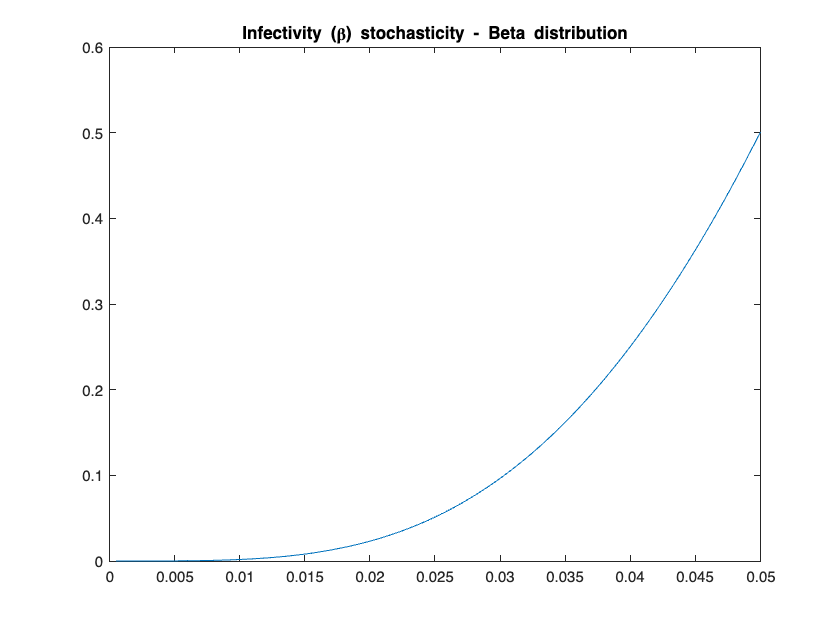

% Infectivity (beta) parameter stochasticity
x_beta = 0.0005:0.0005:0.05;
beta_pdf = betapdf(x_beta,5,20);
plot(x_beta,beta_pdf)
title("Infectivity (\beta) stochasticity - Beta distribution")
% Recovery (gamma) parameter stochasticity
x_gamma = 0.1:0.002:0.3;
gamma_pdf = betapdf(x_gamma,10,8);
plot(x_gamma,gamma_pdf)
title("Recovery (\gamma) stochasticity - Beta distribution")
% Verification for stochastic parameter values
for i=1:length(beta_pdf)

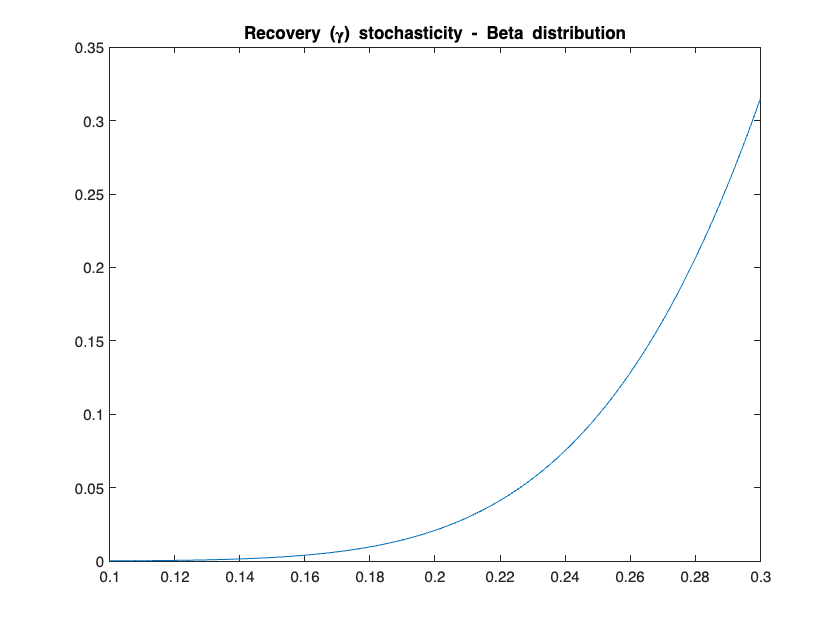

    assert(all(beta_pdf(i) >= 0 & beta_pdf(i) <= 1), "Error in stochastic beta parameter value!")
    assert(all(gamma_pdf(i) >= 0 & gamma_pdf(i) <= 1), "Error in stochastic gamma parameter value!")
end

% Time period

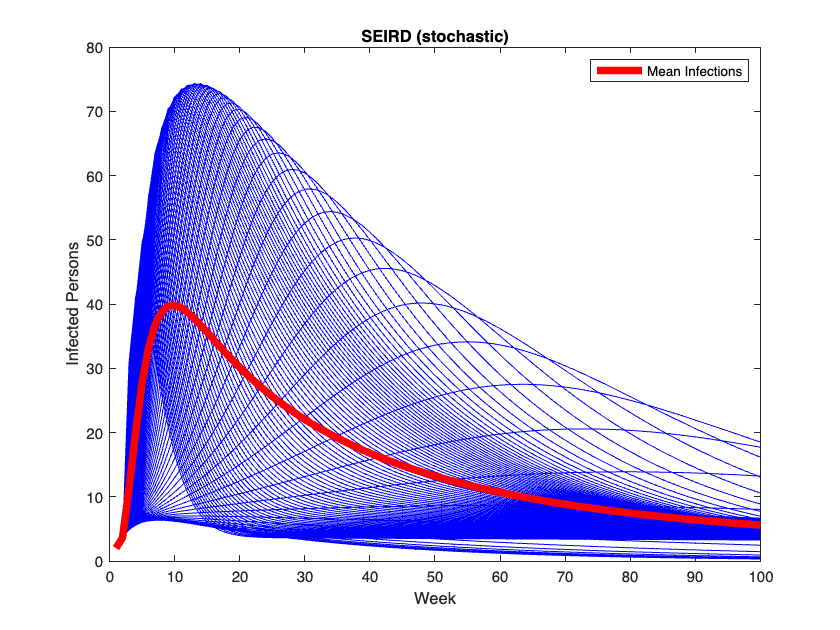

timestep = 100;

% Initial number of people
i_0 = 2;         
s_0 = 100 - i_0;
r_0 = 0;
e_0 = 6;
d_0 = 0;

rng(101)

I_ensemble = zeros(timestep, length(beta_pdf));

for i=1:length(beta_pdf)

    beta_pdf_temp = beta_pdf(i);
    gamma_pdf_temp = gamma_pdf(i);

    % SEIRD simulation
    [Sn, En, In, Rn, Dn, Wn] = simulate_seird(s_0 - e_0, e_0, i_0, r_0, d_0, ...
        alpha_n, beta_pdf_temp, gamma_pdf_temp, delta_n, sigma_n, timestep);

    I_ensemble(:, i) = sum(In, 1);
 
end

I_mean = mean(I_ensemble, 2);

% Conditions
assert(all(abs(Sn + En + In + Rn + Dn - 100) < 1e-3), "Conservation of People Violated!")

assert(all(Sn>=0)||all(En>=0)||all(In>=0)||all(Rn>=0)||all(Dn>=0), "Negative People!")

assert(all(Sn<=100)||all(En<=100)||all(In<=100)||all(Rn<=100)|| all(Dn<=100), "Extra People Found!")

assert(all((Dn(2:end)-Dn(1:(end-1)))>=0), "Dead People decreasing!")


% Plot SEIRD (stochastic) infections
plot(Wn, I_ensemble, 'b-', 'LineWidth', 0.1, 'HandleVisibility','off');
hold on;
plot(Wn, I_mean, 'r-', 'LineWidth', 5, 'DisplayName', 'Mean Infections');
hold off;
xlabel("Week")
ylabel("Infected Persons")
legend()

title("SEIRD (stochastic)")
% Plot SEIRD (stochastic) peak infections for takeoff simulations vs all simulations
I_ensemble_high = zeros(timestep, length(beta_pdf));

for i=1:100

    if (max(I_ensemble(:,i)) > 50) && (30<=i) && (i<=100)
        I_ensemble_high(:,i) = I_ensemble(:,i);

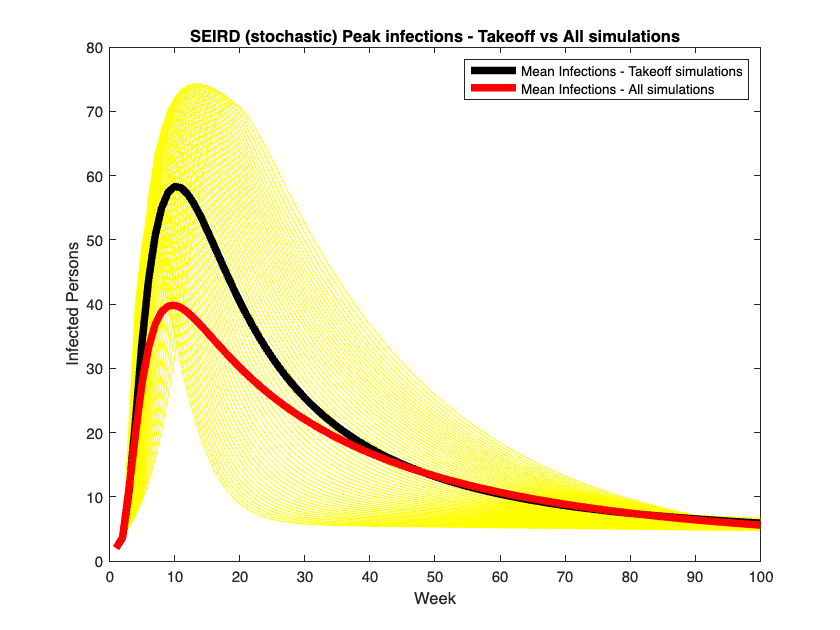

        plot(Wn, I_ensemble(:,i), 'y-', 'LineWidth', 0.1, 'HandleVisibility','off');
        hold on;
    end

end

I_mean_high = mean(I_ensemble_high(:,30:86), 2);
plot(Wn, I_mean_high, 'k-', 'LineWidth', 5, 'DisplayName', 'Mean Infections - Takeoff simulations');
plot(Wn, I_mean, 'r-', 'LineWidth', 5, 'DisplayName', 'Mean Infections - All simulations');

hold off;
xlabel("Week")
ylabel("Infected Persons")
legend()
title("SEIRD (stochastic) maximum infections - Takeoff vs All simulations")

% Plot SEIRD (stochastic)
plot(Wn, Sn, 'b-', 'LineWidth', 1, 'DisplayName', 'Susceptible');
hold on;
plot(Wn, En, 'g-', 'LineWidth', 1, 'DisplayName', 'Exposed');
plot(Wn, I_mean, 'r-', 'LineWidth', 1, 'DisplayName', 'Infectious');
plot(Wn, Rn, 'c-', 'LineWidth', 1, 'DisplayName', 'Recovered');

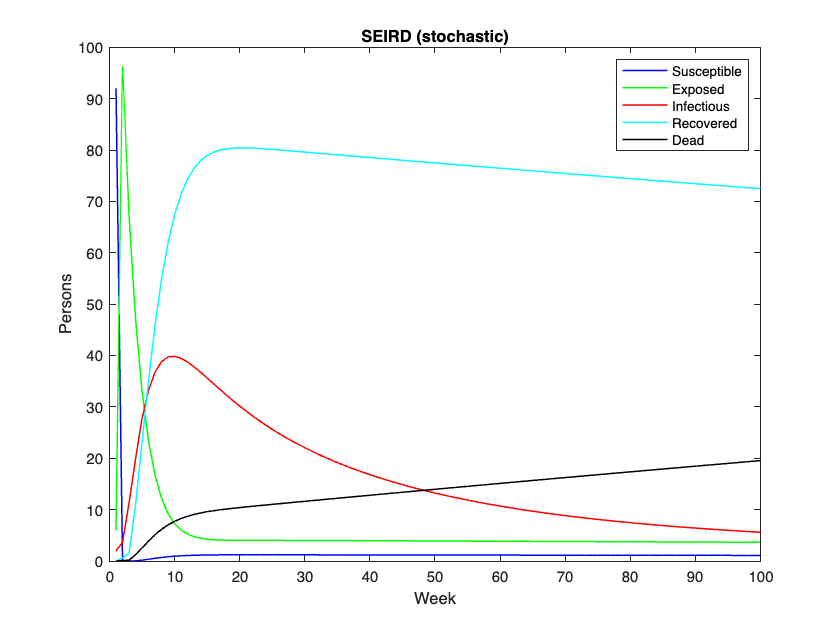

plot(Wn, Dn, 'k-', 'LineWidth', 1, 'DisplayName', 'Dead');
hold off;
xlabel("Week")
ylabel("Persons")
legend()
title("SEIRD (stochastic)")
% Plot SEIRD (Deterministic) vs SEIRD (Stochastic)
plot(W, I, 'b-', 'LineWidth', 1, 'DisplayName', 'SEIRD (Deterministic)');
hold on;
plot(Wn, I_mean, 'r-', 'LineWidth', 1, 'DisplayName', 'SEIRD (Stochastic)');
hold off;
xlabel("Week")
ylabel("Infected Persons")

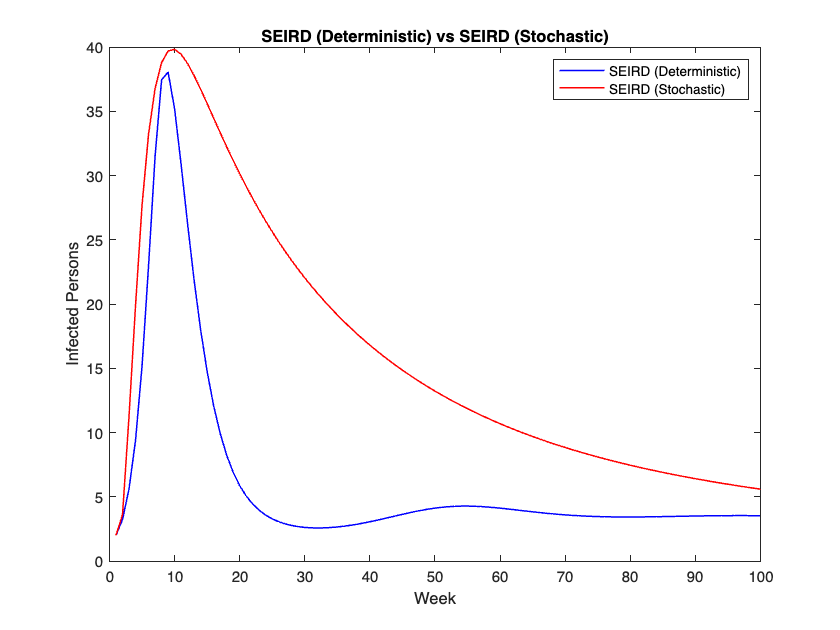

legend()
axis([0,100,ylim()]);
title("SEIRD (Deterministic) vs SEIRD (Stochastic)")

The values of stocks for the SEIRD model after the end of the simulation at 100 weeks of time can also be seen from the plot.